# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 06-Dec-2019 10:58:59

## Create the Layer Graph

Create the layer graph variable to contain the network's layers.

lgraph = layerGraph();

## Add the Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([227 227 3],"Name","imageinput_2")
    convolution3dLayer([3 3 3],32,"Name","conv3d_1","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    imageInputLayer([227 227 3],"Name","imageinput_1")
    convolution3dLayer([3 3 3],32,"Name","conv3d_2","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_2")
    regressionLayer("Name","regressionoutput_1")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_1")
    regressionLayer("Name","regressionoutput_2")];
lgraph = addLayers(lgraph,tempLayers);

## Connect the Layer Branches

Connect all the branches of the network to create the network's graph.

lgraph = connectLayers(lgraph,"conv3d_1","addition_2/in1");
lgraph = connectLayers(lgraph,"conv3d_1","addition_1/in2");
lgraph = connectLayers(lgraph,"conv3d_2","addition_2/in2");
lgraph = connectLayers(lgraph,"conv3d_2","addition_1/in1");

## Clean Up Helper Variable

clear tempLayers;

## Plot the Layers

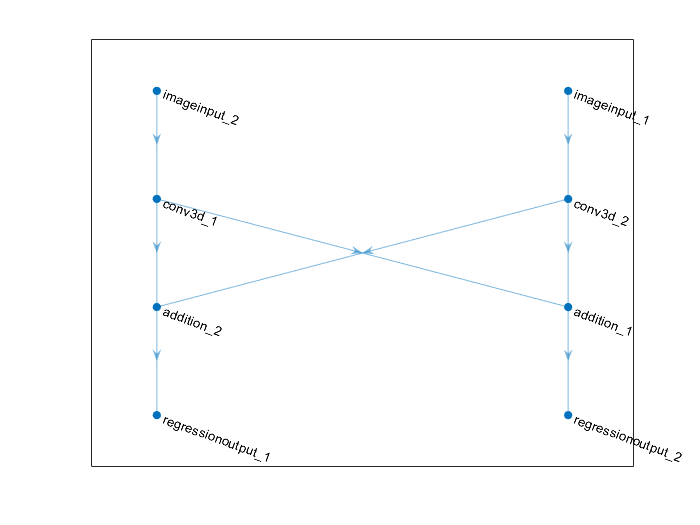

plot(lgraph);